Paso 1 

Aplicar una entrada tipo escalon al proceso en lazo abierto.

num = [0.25];
den = [1, 0.9, 0.25];%<-- Aquí modifiqué zeta intencionalmente
G = tf(num, den)


G =
 
         0.25
  ------------------
  s^2 + 0.9 s + 0.25
 
Continuous-time transfer function.
Model Properties


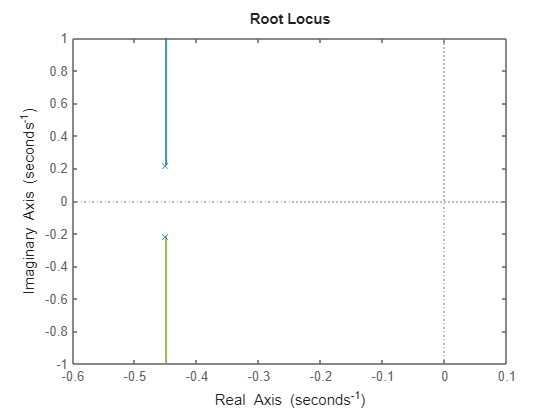

figure;
rlocus(G)

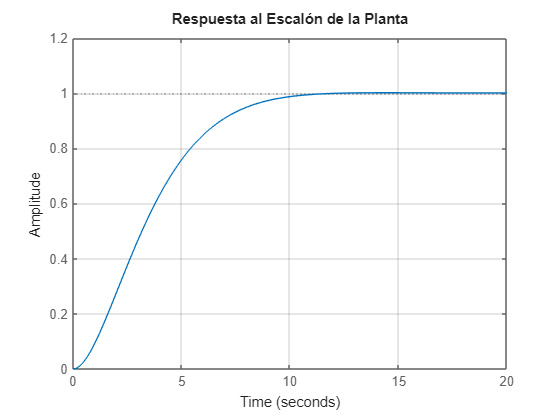

figure;
step(G);
xlim([0, 20]);

title('Respuesta al Escalón de la Planta');
grid on;

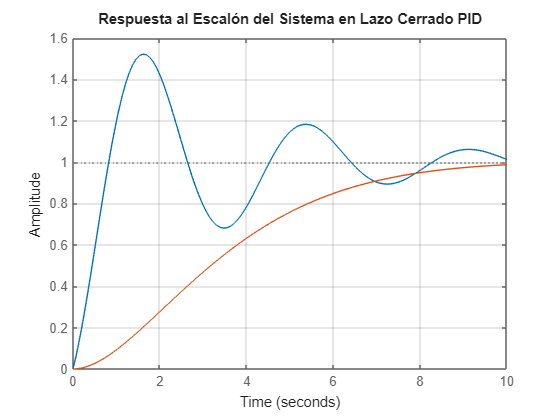


Kp = 13.2; % Ganancia proporcional (ajustar según el sistema)
Ti = 1; % Tiempo integral (ajustar según el sistema)
Td = 0.25; % Tiempo derivativo (ajustar según el sistema)

% Controlador PID
C = pid(Kp, Kp/Ti, Kp*Td);

T = feedback(C*G, 1);

figure;
step(T);
xlim([0, 10]);
title('Respuesta al Escalón del Sistema en Lazo Cerrado PID');
grid on;
hold on
step(G);
hold off

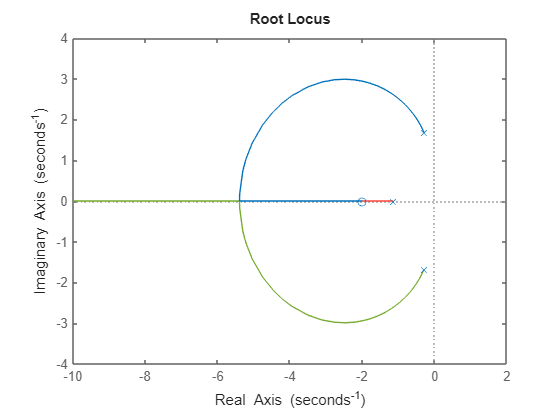

figure;
rlocus(T)